d = inputs;
mp = mesh_points(d.number_of_points_array);


explicit = readmatrix("exports\1D\100_explicit.csv");
s0_explicit = readmatrix("exports\1D\s0_100_explicit.csv");
s1_explicit = readmatrix("exports\1D\s-1_100_explicit.csv");
s2_explicit = readmatrix("exports\1D\s-2_100_explicit.csv");
s3_explicit = readmatrix("exports\1D\s-3_100_explicit.csv");

space = linspace(0, d.total_distance, d.number_of_points_array)

space =          0    5.0505   10.1010   15.1515   20.2020   25.2525   30.3030   35.3535   40.4040   45.4545   50.5051   55.5556   60.6061   65.6566   70.7071   75.7576   80.8081   85.8586   90.9091   95.9596  101.0101  106.0606  111.1111  116.1616  121.2121  126.2626  131.3131  136.3636  141.4141  146.4646  151.5152  156.5657  161.6162  166.6667  171.7172  176.7677  181.8182  186.8687  191.9192  196.9697  202.0202  207.0707  212.1212  217.1717  222.2222  227.2727  232.3232  237.3737  242.4242  247.4747


max_time  = mp.t_number_of_points;
step_time = floor(mp.t_number_of_points/20);

TIME_CONTROL =40

TIME_CONTROL = 63

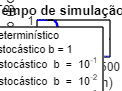

plot(space,explicit(:, TIME_CONTROL), 'k-','LineWidth',1.5);
ylim([0,d.C_x1]);
grid; 

xlabel('Distância (m)'); 
ylabel('Concentração (Bq/m³)');
title("Tempo de simulação " + num2str(TIME_CONTROL*mp.delta_t, 2) + " s");

hold on 

plot(space,s0_explicit(:, TIME_CONTROL), 'k--','LineWidth',1.5);
plot(space,s1_explicit(:, TIME_CONTROL), 'r--','LineWidth',1.5);
plot(space,s2_explicit(:, TIME_CONTROL), 'g--','LineWidth',1.5);
plot(space,s3_explicit(:, TIME_CONTROL), 'b--','LineWidth',1.5);

hold off

legend('Determinístico', 'Estocástico b = 1', 'Estocástico b = 10^{-1}', 'Estocástico b = 10^{-2}', 'Estocástico b = 10^{-3}')

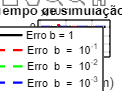


error0 = explicit - s0_explicit;
error1 = explicit - s1_explicit;
error2 = explicit - s2_explicit;
error3 = explicit - s3_explicit;
% relative_error = error./explicit;
% relative_error(relative_error == -Inf) = 0;

plot(space,error0(:, TIME_CONTROL), 'k-','LineWidth',1.5);
grid; 

xlabel('Distância (m)'); 
ylabel('Erro');
title("Tempo de simulação " + num2str(TIME_CONTROL*mp.delta_t, 2) + " s");

hold on 
plot(space,error1(:, TIME_CONTROL), 'r--','LineWidth',1.5);
plot(space,error2(:, TIME_CONTROL), 'g--','LineWidth',1.5);
plot(space,error3(:, TIME_CONTROL), 'b--','LineWidth',1.5);

hold off

legend('Erro b = 1', 'Erro b = 10^{-1}', 'Erro b = 10^{-2}', 'Erro b = 10^{-3}')